# Improved DMP-Based Robot Learning using GMM-GMR for Trajectory Generation and Control  

## **1. INTRODUCTION**

This report uses GMM and GMR as the forcing term learners for DMPs, instead of the usual WLR method. First, the number of Gaussian components K is chosen, which sets how many clusters will represent the trajectory. The GMM is trained with the EM algorithm, giving each cluster a mean, covariance, and mixing weight. The mixing weight shows what share of the data belongs to each cluster. Based on the referred paper[1], After training, GMR is used to find the forcing term at any given canonical state s. To do this, the normalised responsibility (Eq.3) for each Gaussian component is calculated, showing how relevant each one is at the chosen state. Next, the conditional mean and covariance of each Gaussian are found (Eq.1,2). The final predicted forcing term comes from adding up the conditional means, each weighted by its responsibility (Eq.4), and the covariance is calculated in the same way (Eq.5).

                                  (1)

                                         (2)

                                            (3)

                                                                     (4)

                                                                (5)

Following this step, the result obtained from the GMR is scaled by multiplying it by the canonical system state s and the factor (g − x₀), where g is the desired end point and x₀ is the starting point. The modified input is fed into the DMP Equation (Eq. 6), which treats it as a nonlinear input for shaping the acceleration behavior towards the target.          

                               (6)                     

                                                                                    (7)

## 2. ROBOT LEARNING

#### 2.1 Original DMP

As stated in Equation (6), the DMP models robot motion as a spring-damper system, where β is the stiffness factor that drives the system toward the goal     g, and α is the damping factor that prevents oscillation during convergence. In the original DMP formulation, the nonlinear forcing term f(s) is approximated using Radial Basis Functions ( ) fitted via Locally Weighted Least Squares ( ). Each RBF is a Gaussian bell curve centred at a fixed point along the canonical state s , conceptually similar to the K Gaussian components in GMM, but with centres placed at equal intervals in s-space rather than learned from the data. 

Here   is given as  

Dataset parameters

nbData = 200;               % Length of each demo trajectory 
nbDemos = 5;                % Number of demonstrations for the DMP training

Load handwriting trajectories

demos = [];
load('Demonstrations.mat');
demos_in = {demos{1:nbDemos}};


Parameters for Original DMP

nStates = 9;                % Number of activation functions (i.e., number of states in the forcing term)
nVar = 3;                   % Number of variables [s,f1,f2] (decay term and perturbing force)
beta = 50;                  % Stiffness gain (β)
alpha = (2*beta)^.3;        % Damping gain (with ideal underdamped damping ratio) (α)
decayFactor = 1.1;          % Decay factor (a in τx'=-ax)
dt = 0.01;                  % Duration of time step (τ)

dmp = SkillGeneralisation(nVar, nStates, beta, alpha, dt);   % Class constructor
dmp = dmp.canonicalSystemInitialisation(decayFactor, nbData);
dmp = dmp.trajectort2Forcing(demos_in);

Regression with Locally Weighted Linear Regression (WLR)

fWLR = dmp.fittingWithLocallyWLS();

trajWLR = dmp.forcing2Trajectory(fWLR);

Spatial plot

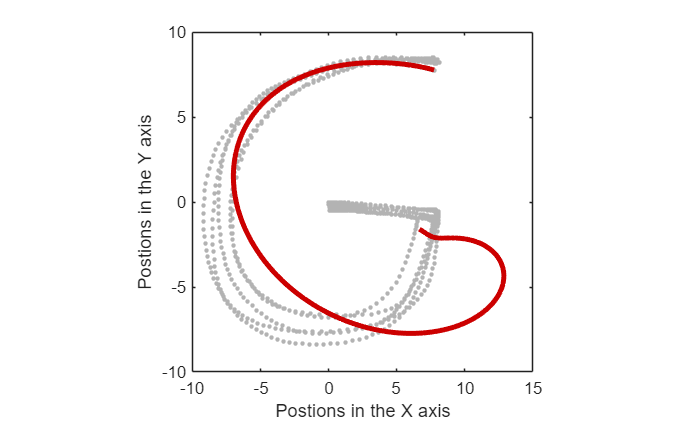

figure,
for n = 1:nbDemos
    plot(demos_in{n}.pos(1,:), demos_in{n}.pos(2,:),'.','markersize',8,'color',[.7 .7 .7]); hold on
end
plot(trajWLR(1,:),trajWLR(2,:),'-','linewidth',3,'color',[.8 0 0]);
xlabel('Postions in the X axis')
ylabel('Postions in the Y axis')
axis equal; axis square; 

                                                              WLR based Trajectory                                                  

#### 2.1.1 Plots with different Parameters  

   (keeping other parameters fixed(k = 15 , decay_factor = 1.1 )

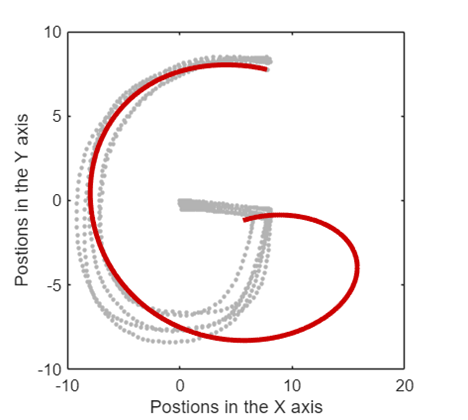 

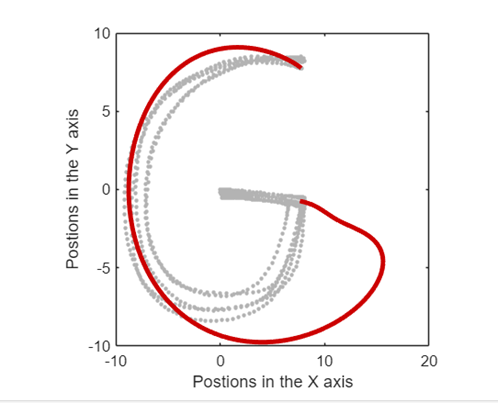

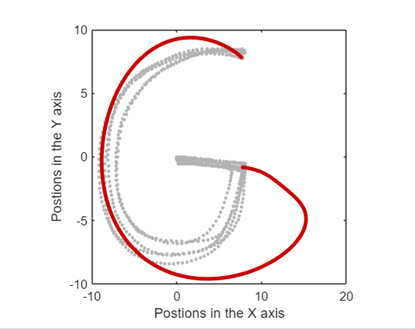

 keeping other parameters fixed(decay_factor = 1.1,  $\beta$ = 50 )

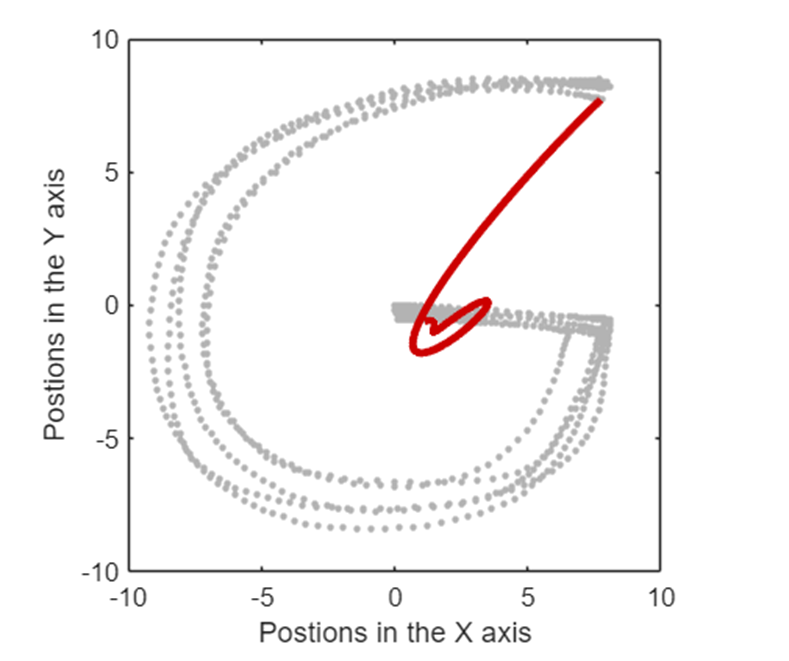                               

                   k = 3                                                                                                                                               

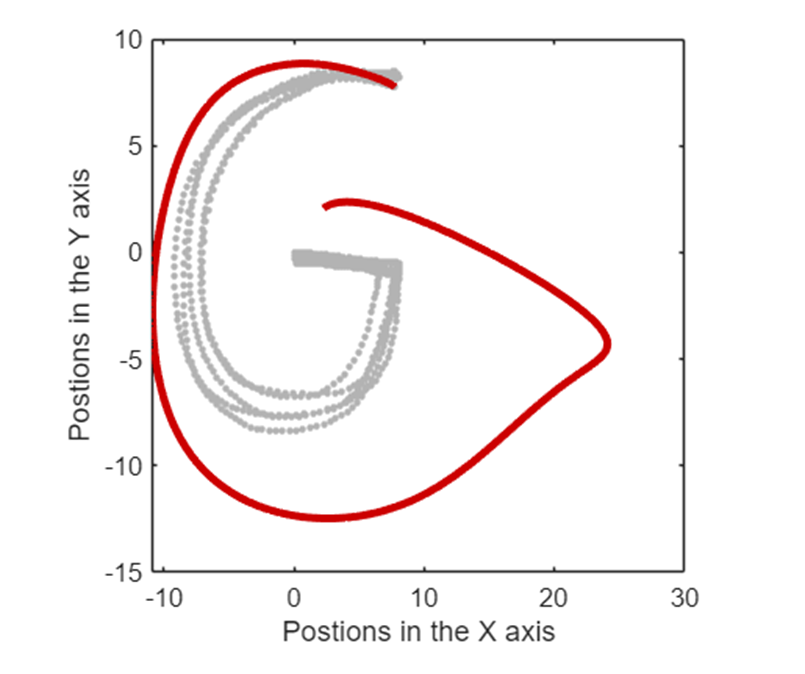

                         k = 50

   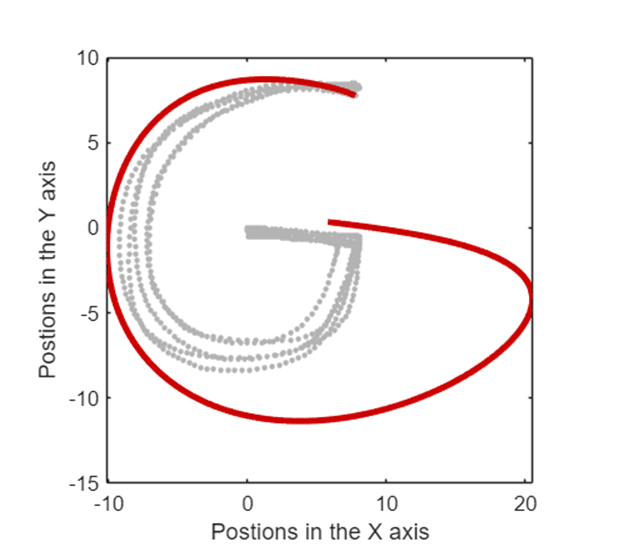

                           k =  20    

        keeping other parameters fixed(k = 15 ,  $\beta$ = 50 )

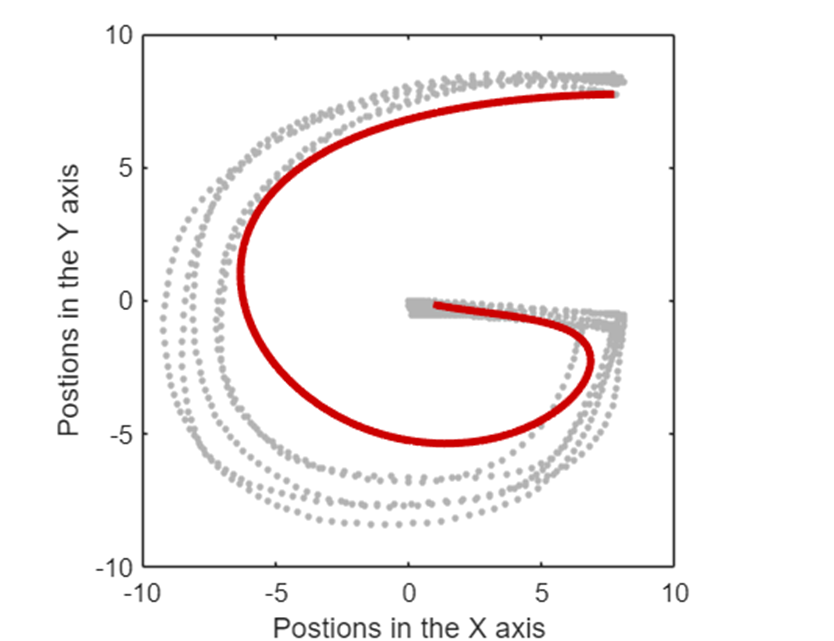                           

                    decayfactor = 0.2                                                                                                               

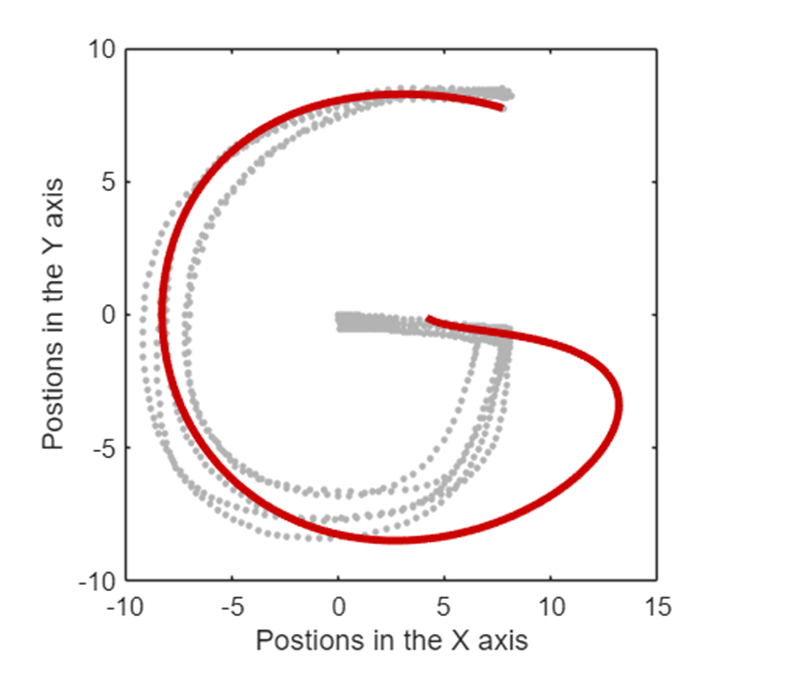

                decayfactor = 0.8 

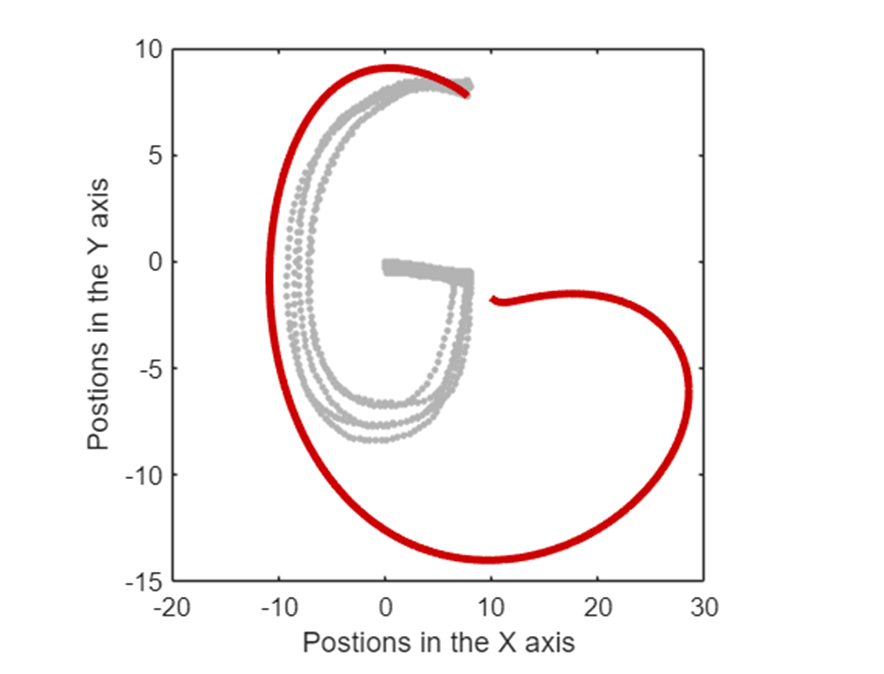

                    decayfactor = 1.5

### 2.2 GMM + GMR

Dataset parameters

nbData = 200;               % Length of each demo trajectory 
nbDemos = 5;                % Number of demonstrations for the DMP training

Define DMP parameters

nStates = 9;                % Number of activation functions (i.e., number of states in the forcing term)
nVar = 3;                   % Number of variables [s,f1,f2] (decay term and perturbing force)
beta = 50;                  % Stiffness gain (β)
alpha = (2*beta)^.3;        % Damping gain (with ideal underdamped damping ratio) (α)

decayFactor = 1.1;          % Decay factor (a in τx'=-ax)
dt = 0.01;                  % Duration of time step (τ)

Initialise the DMP instance

dmp = SkillGeneralisation(nVar, nStates, beta, alpha, dt);   % Class constructor
dmp = dmp.canonicalSystemInitialisation(decayFactor, nbData);
dmp = dmp.trajectort2Forcing(demos_in);

#### 2.2.1  Log-Likelihood Curve

The log-likelihood curve exhibits numerical convergence after approximately 50 iterations, indicating that the Expectation-Maximization (EM) algorithm has successfully reached a stable parameter plateau.

   200     2



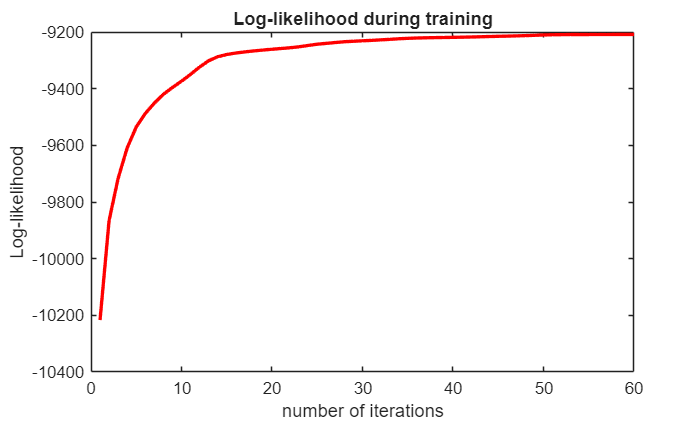

fGMR = dmp.fittingWithGMR() ;

#### **2.2.2   Confidence Graph**

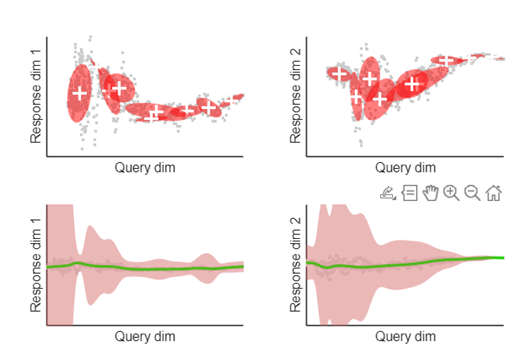

*       GMM components (top) and GMR regression with confidence intervals*

The GMM in the top row groups the demonstrations into adaptive Gaussian clusters. The size and orientation of each red ellipse show the correlation and local variance at each stage of the movement. When GMR is applied in the bottom row, the model turns these noisy clusters into a smooth and reliable forcing signal, shown in green. The pink envelope measures the uncertainty in the demonstrations, helping the robot decide which parts of the 'G' need high precision and which parts can be more flexible.

trajGMR = dmp.forcing2Trajectory(fGMR);

#### **Spatial plot**

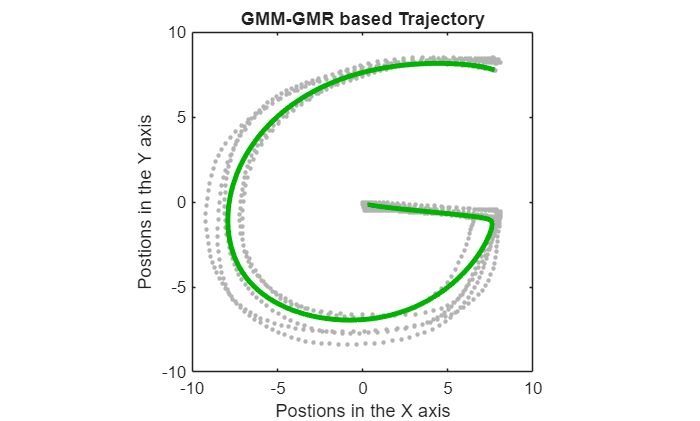

figure,
for n = 1:nbDemos
    plot(demos_in{n}.pos(1,:), demos_in{n}.pos(2,:),'.','markersize',8,'color',[.7 .7 .7]); hold on
end
plot(trajGMR(1,:),trajGMR(2,:),'-','linewidth',3,'color',[0 .7 0]);
xlabel('Postions in the X axis')
ylabel('Postions in the Y axis')
title("GMM-GMR based Trajectory")
axis equal; axis square; hold off

#### **2.2.3 Normalising forcing Term**

When we normalise the forcing term by the movement amplitude  , we achieve spatial invariance. This step is important because it lets the DMP adapt to new goal locations. If we skip normalisation (see Figure 1), the learned forcing term keeps a fixed size that does not match the new movement, which leads to noticeable geometric distortion. However, when we scale the force based on the new goal distance (see Figure 2), the proportions of the 'G' shape stay the same. This allows the robot to generalise the skill accurately in different workspaces.

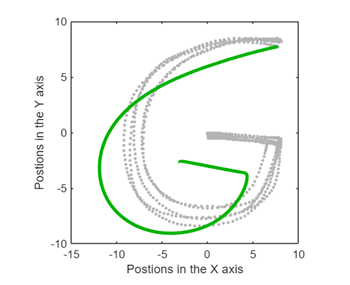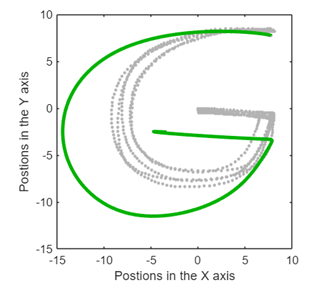

* DMP generalization to goal (-3, -3) showing geometric distortion without normalization (left) versus preserved spatial invariance with normalization (right)*

### **3. Evaluation **

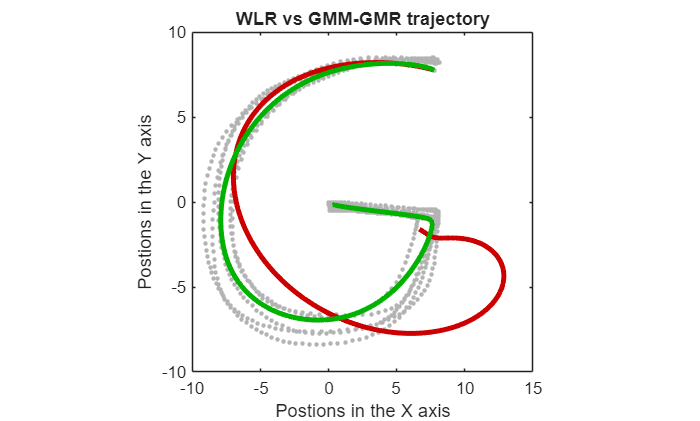

figure,
for n = 1:nbDemos
    plot(demos_in{n}.pos(1,:), demos_in{n}.pos(2,:),'.','markersize',8,'color',[.7 .7 .7]); hold on
end
plot(trajWLR(1,:),trajWLR(2,:),'-','linewidth',3,'color',[.8 0 0]);
plot(trajGMR(1,:),trajGMR(2,:),'-','linewidth',3,'color',[0 .7 0]);
xlabel('Postions in the X axis')
ylabel('Postions in the Y axis')
title("WLR vs GMM-GMR trajectory")
axis equal; axis square; hold off

**3.1  Number of Demonstration vs Trajectory**

NumDemos   RMSE      MaxError
1          4.2566    8.5735
2          4.6444    7.6738
3          4.8048    7.0079
4          4.7622    7.0227
5          5.1608    7.4122
Best = 1 demos  RMSE = 4.2566


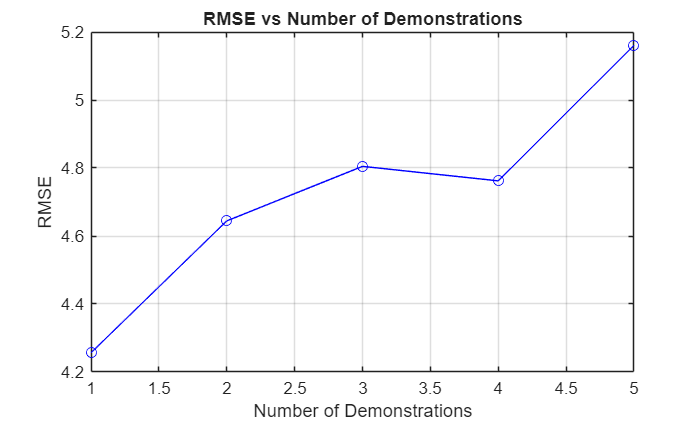

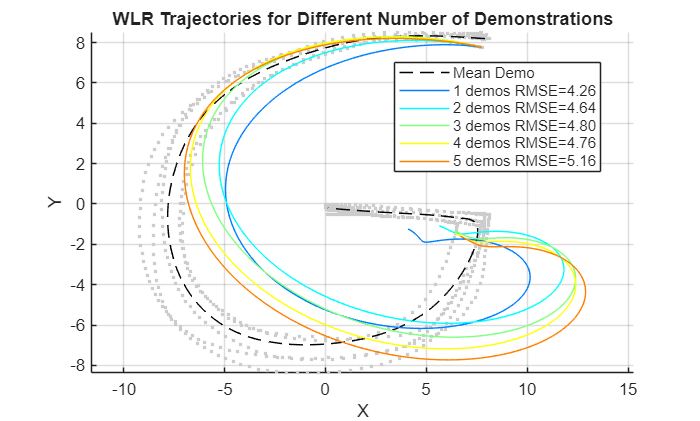

% function to plot number RMSE value vs number of demo 
SkillGeneralisation.compareDemosWLR(demos_in, nbData, beta, alpha, dt, nStates);

NumDemos   RMSE      MaxError
1          FAILED
   200     2

2          1.3589    2.5254
   200     2

3          0.6645    1.5436
   200     2

4          0.3551    0.6719
   200     2

5          0.3467    0.8388
Best = 5 demos  RMSE = 0.3467


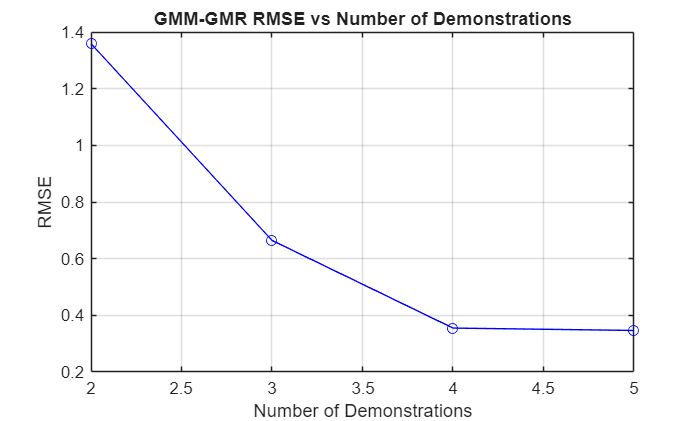

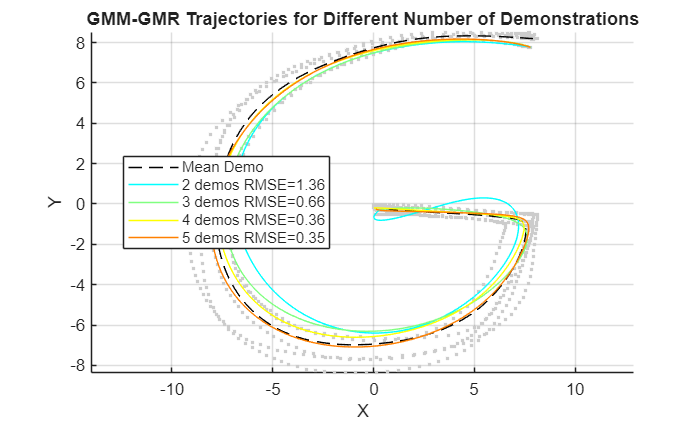

SkillGeneralisation.compareDemos(demos_in, nbData, beta, alpha, dt, nStates);

The analysis shows that the number of demonstrations has a key role in determining the quality of the trajectory produced by the algorithm. When only one demonstration is used, i.e., nDemos=1, the learning algorithm becomes highly sensitive to noise present during trials. Consequently, the algorithm produces an RMSE value of 2.96 due to overfitting to trial noise. Nevertheless, the RMSE curve exhibits a decreasing trend as the number of demonstrations increases, allowing errors to be minimised using statistical averaging techniques. The RMSE plot demonstrates an asymptotic behaviour that decreases rapidly to an RMSE value of 0.34 for Demos =4 .

GMM–GMR clusters observations by using the joint probability of the data and looking at their density. On the other hand, WLR is a regression method that gives every data point the same importance, no matter how well it matches the overall movement pattern, and calculates weights using the canonical variable x.

The WLR–DMP model does not scale as well as the GMM–GMR framework when more demonstrations are added. Raising the number of demonstrations from 1 to 5 does not lower the error much, with RMSE values staying close to 5.16. This happens because fixed-width RBF kernels are inflexible to adjust their covariance, so they cannot capture changes in the data or filter out noise. When more demonstrations are included, small timing differences get averaged, which causes a smearing effect and makes the trajectory less accurate.

#### 3.2  Number of  K vs Trajectory

nStates    RMSE      MaxError
3          6.0880    10.1657
5          5.0465    10.5865
7          4.7708    8.5606
9          5.1608    7.4122
12          6.0709    9.1764
15          6.8198    11.3624
20          7.6516    13.6697
25          8.1662    15.0233
30          8.5045    15.9252
50          9.1105    17.8066
Best K = 7  RMSE = 4.7708


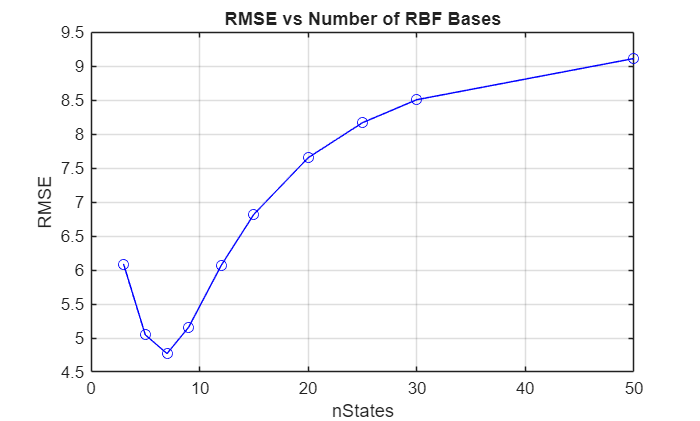

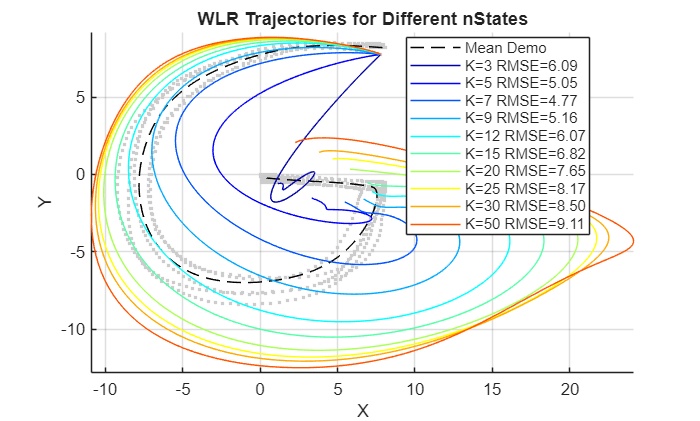

% function to plot number RMSE value and maxError vs number of K (number of
% kernels)
SkillGeneralisation.compareKvaluesWLR(...
    dmp.dataTraining, ...
    demos_in, ...
    dmp.xIn, ...
    nbData, ...
    [3, 5, 7, 9, 12, 15, 20, 25, 30, 50], ...
    beta, alpha, dt, ...
    dmp.endPos, dmp.startPos, dmp.numVarPos, dmp.numDemos);

K          RMSE      MaxError
   200     2

3          0.8569    1.7019
   200     2

5          0.4336    0.8411
   200     2

7          0.3411    0.5600
   200     2

9          0.4392    1.0928
   200     2

12          0.3494    0.8372
   200     2

15          0.3630    0.8356
   200     2

20          0.3550    0.6287
   200     2

25          0.3950    0.7231
   200     2

30          0.3758    0.6941
50          FAILED
Best K = 7  RMSE = 0.3411


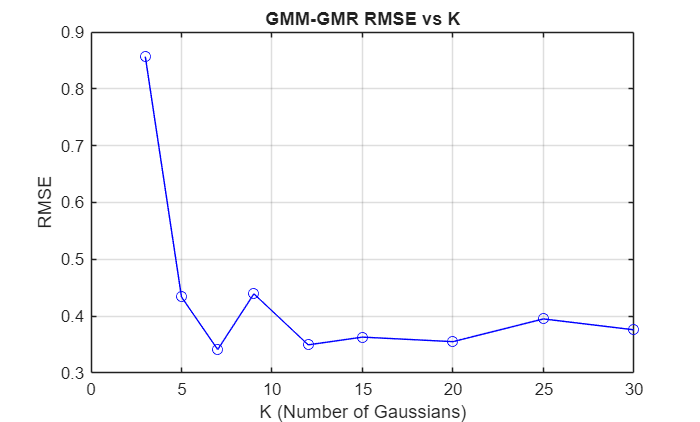

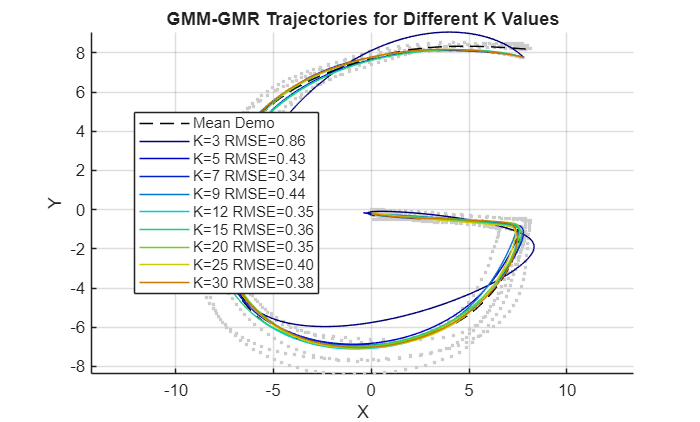

% function to plot number RMSE value and maxError vs number of K (number of gaussian cluster)
SkillGeneralisation.compareKvalues(dmp.dataTraining,demos_in,dmp.xIn, nbData, ...
[3, 5, 7, 9, 12, 15, 20,25, 30 ,50], ...
beta, alpha, dt, ...
dmp.endPos, dmp.startPos, dmp.numVarPos);

The graphs show that in both cases, there is an optimal range of K where the RMSE is much lower than at extreme values. When K is small, the model cannot capture the trajectory well, so the RMSE is higher. When K is very large, the model starts to overfit by learning noise in the data, which distorts the trajectory.

Looking at the RMSE values, even with a low K=3, the Gaussian model has an RMSE of 0.86, while the WLR method gives 5.97, which is almost six times higher. Both methods perform best when K is between 10 and 20. These results show that GMM/GMR models the trajectory more accurately than WLR.  

#### 3.3  $\beta
$ (stiffness constant) & $\alpha
$(damping constant) & decay_factor(x)

$\beta
$ (stiffness), $\alpha$ (damping), and the decay factor do not have much impact on the shape of the GMM-GMR reconstructed trajectory . This happens because the forcing term is calculated using these parameters during training, and the same values are used again during reconstruction, so their effects cancel each other out.Since the Gaussians adjust to whatever forcing term comes from any beta and alpha values. 

In contrast, the WLR method uses fixed, equally spaced RBF basis functions.  Changing these parameters changes the regression problem, so each combination produces a different trajectory.

However, while these terms have limited influence on trajectory generation, they play an important role in the system dynamics. Specifically, they determine how the system converges to the goal, influencing stability, convergence speed, and the forces acting near the final position.This effect is further illustrated with a simple experiment in Section 4.3 (Kinematics).

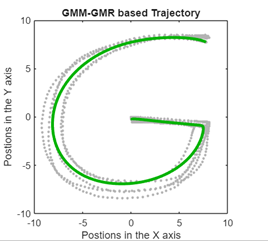     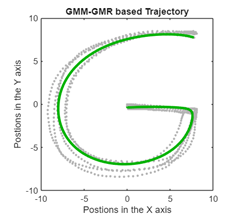

      $\beta =80$                        decayfactor = 0.7

### **4: Kinematic Simulation**


save("LearnedTrajectory.mat",'trajGMR');
LearnedTrajectory = load("LearnedTrajectory.mat")

LearnedTrajectory = struct with fields:
    trajGMR: [2×200 double]


X_pos = LearnedTrajectory.trajGMR(1,:)';
Y_pos = LearnedTrajectory.trajGMR(2,:)';
X_offset = 2.5

X_offset = 2.5000

Y_offset = 9.5

Y_offset = 9.5000

retrievedTraj = [X_pos + X_offset, Y_pos + Y_offset]; 
retrievedTraj_time = linspace(0, 1, size(retrievedTraj, 1))';
dataset = timeseries(retrievedTraj, retrievedTraj_time, 'Name', 'SimData');
save("SimData.mat", "dataset", "-v7.3");

#### **4.1 Plots **

      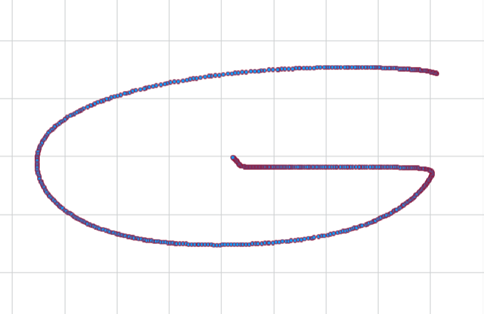              

           Generated trajectory

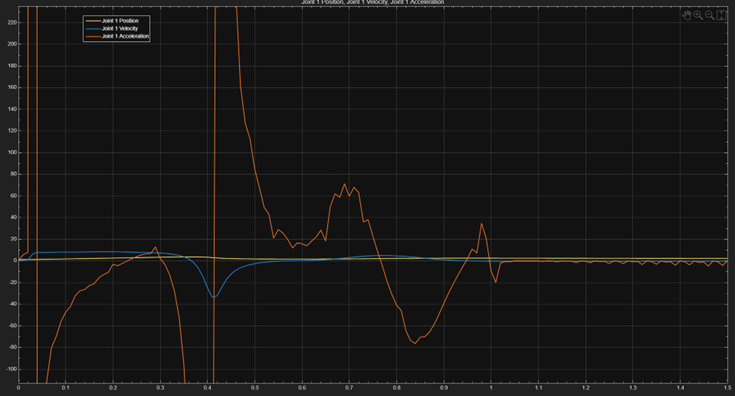

                                                                figure : joint_1 kinematics

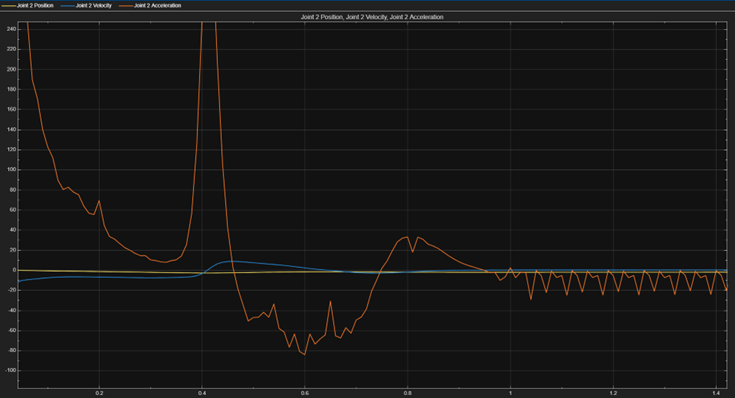

         figure : joint_2 kinematics

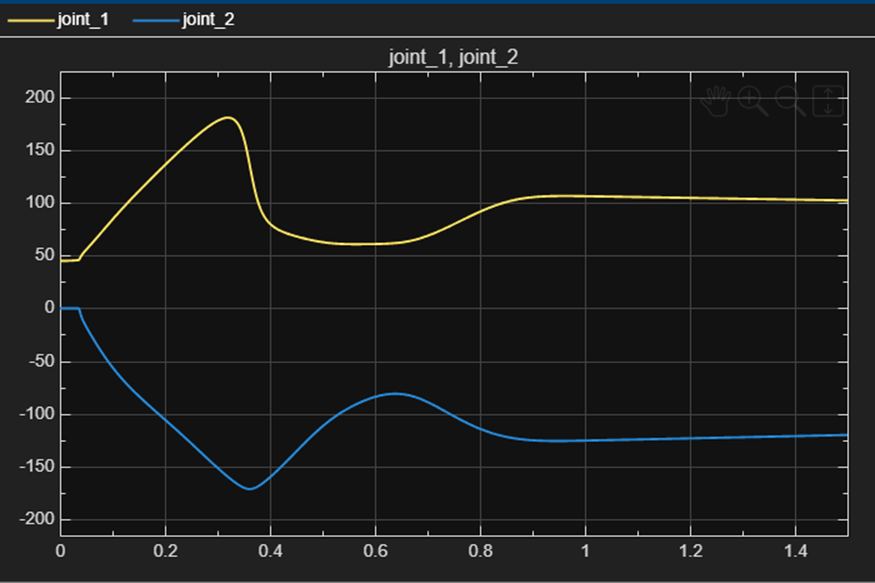

       figure : Joint angles (degree)

The graphs reveal **excessively high joint velocities and accelerations** for a 1-second trajectory. Joint 1's acceleration spikes sharply, while Joint 2 approaches 180° near 0.3 seconds, triggering a **singularity**. Consequently, these kinematics are physically unfeasible for real-world mechanical systems.

#### **4.2 Inverse Kinematics equation**

For joint_2 angle  , using the law of cosines:

To ensure numerical stability and avoid simulation issues, the value of   is bounded within a valid range

 

Enforcing the elbow-down configuration:

Now for joint1_angle ( 

#### 4.3 Effect of  $\beta \;\left(\textrm{stiffness}\right)$ and $\alpha$(damping)

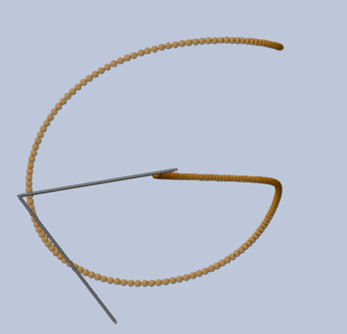

$\beta \;=50$  $\alpha \;$ = 4 

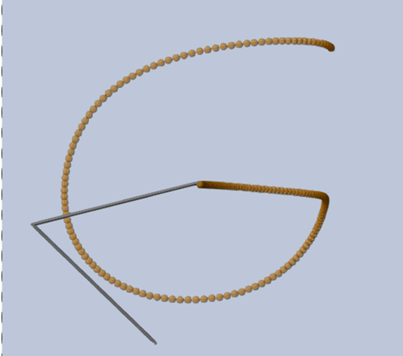  

$\beta \;=50$  $\alpha \;$ = 8 

Given both figures, it can be observed that by changing the damping constant, the robot’s motion can be brought to a stop near the goal position. However, with $\alpha \;$ = 4, the robot continues to move beyond its goal position. These effects can be easily verified through kinematic simulations. 

### **5. Dynamics Simulation**

#### **5.1 Model Designing**

From lecture of week 8 , Applying the Euler–Lagrange equations yields the equations of motion. The final dynamics are expressed in the standard manipulator form

where $M\left(q\right)$ represents the inertia matrix, $C\left(q,\dot{q} \right)$ captures Coriolis and centrifugal effects, and $G\left(q\right)$ represents gravitational forces.

**Since the center of mass is assumed to be at the joints and the system operates in a 2D plane without gravitational effects, the Coriolis/centrifugal and gravity terms become zero.**

Thus, the dynamics reduce to 

#### **5.1.1 Feedback Linearisation Control Design**

The implemented controller is a simplified feedback linearisation (computed torque) approach. Feedback linearisation removes the nonlinear dynamics of the manipulator so the closed-loop system behaves as a simple linear double integrator.  To obtain the virtual control input, a mathematical tool called **Lie derivatives** is used, which systematically differentiates the system dynamics.

This leads to the feedback linearising control law

which cancels the nonlinear terms and reduces the system to a linear double integrator.

So in our case it will be      where the virtual input is designed as 

This results in a linear second-order error system suitable for PD pole placement.

#### 5.1.2 PD Controller Design

 The tracking error is given as    where   is desired value and   is current value.

Taking the Laplace transform, the characteristic equation in the s-plane is obtained as:

For system stability, pole placement in the s-plane is crucial. Placing poles on the negative real axis ensures fast decay without oscillations, and the further left the poles are, the faster the system response.

For a critically damped system ( ) both poles must be real, equal, and negative. After multiple trials, the poles for joint 1 are selected as    and for joint2 as   .

For joint 1:

Comparing with the characteristic equation,

For joint2:

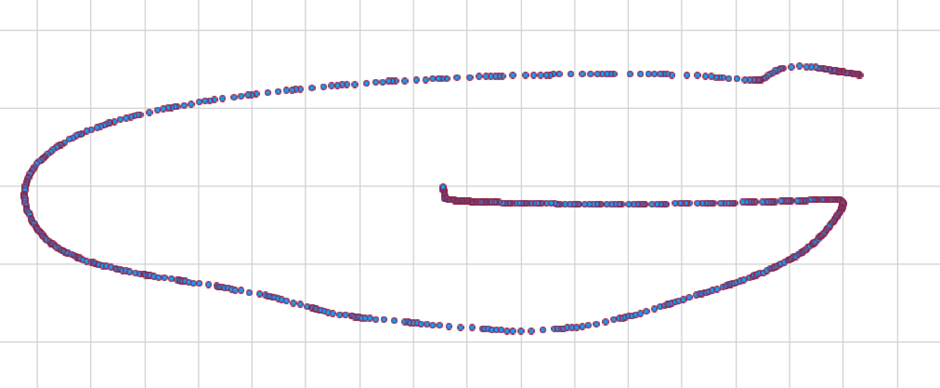                              

         *joint_1 = (s1,s2) = -130 and (joint_2 s1,s2)=-110*

#### **5.2 Plots**

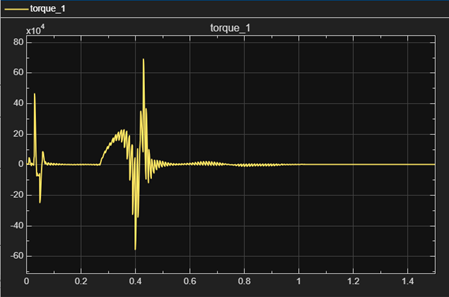                                      

                    Joint_1 Torque                                                                                                                   

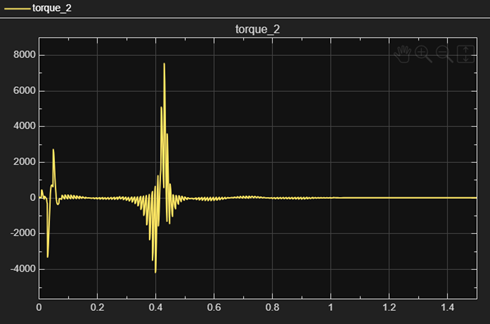

             Joint_2 Torque

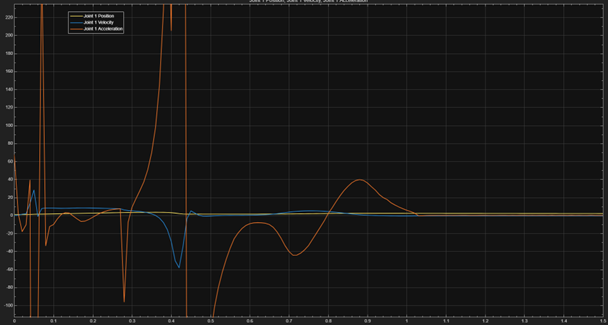

                                                   Dynamics Profile (acceleration, velocity and position) of Joint 1

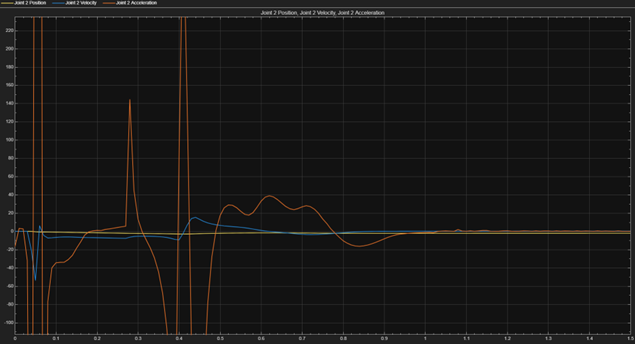

                                                 Dynamics Profile (acceleration, velocity and position) of Joint 2

### **6. Result Analysis**

#### ** 6.1 Trajectory comparision:**

In the trajectory comparison, the kinematic model shows a perfectly aligned trajectory, indicating ideal tracking. However, when implemented with the dynamic model, closely following this trajectory requires extremely high torque, which is not physically feasible for a real system.

The slight deviation (bend) observed in the dynamic response is due to inertia and momentum effects. Even with a high-gain controller, the system is unable to exactly track the desired trajectory, highlighting the limitations of practical implementation compared to ideal kinematic results.

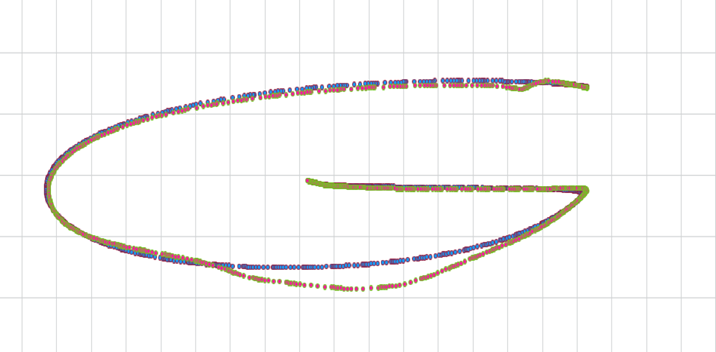   

           Trajectory after implementing Dynamics                                                                            

                                Trajectory with only kinematics

The kinematic results indicate that the system is not feasible for the specified time duration. This is further confirmed when the dynamics are implemented, as both analyses show consistent behaviour. At around 0.3 seconds, the kinematic plots exhibit extremely high acceleration due to a singularity. This effect is clearly reflected in the dynamic torque plots, where the torque sharply increases and exceeds 60,000 Nm.

#### 6.2 Code Block & Simulation Image

**jointPos2Vel**

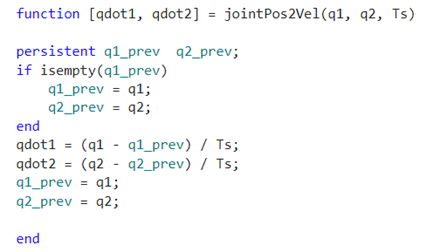

**jointVel2Acc**

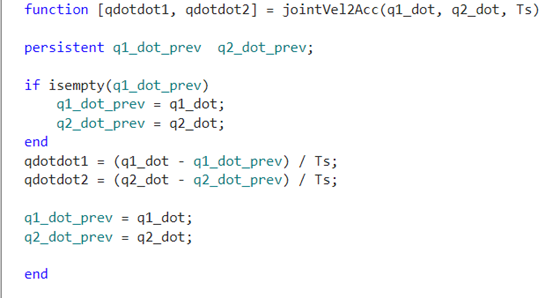

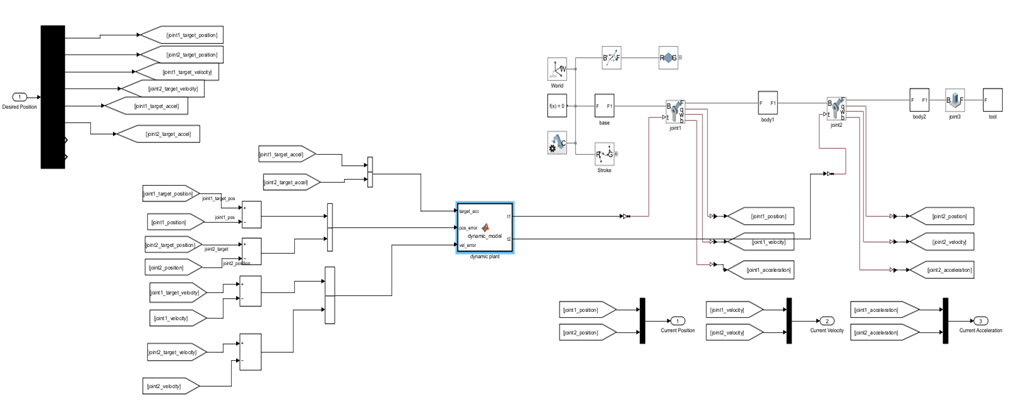

                                                    simulink model of complete model

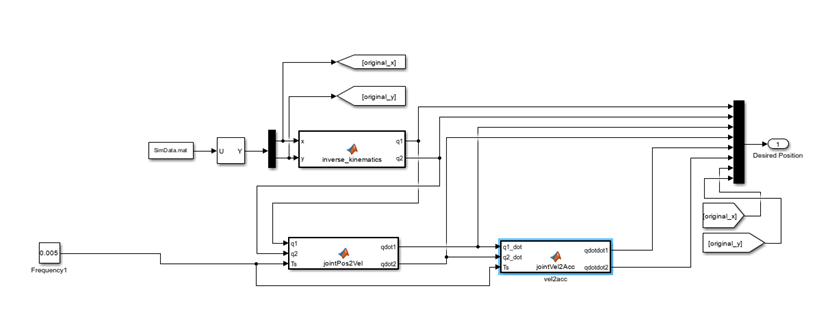

                                                            simulink Model